### Define symbolic variables

syms phi theta psi phi_dot theta_dot psi_dot x_dot y_dot z_dot x y z real;
syms p q r p_dot q_dot r_dot real;
syms U1 U2 U3 U4 real;

% parameters :
m = 1;  % mass in kg 
g = 9.81; % gravity
Ixx = 0.0035;  % moment of inertia x-axis
Iyy = 0.0035;  % moment of inertia y-axis
Izz = 0.005;  % moment of inertia z-axis 
J = 0.0001;   % gyroscopic constant
Omega_h = 500;  % equilibrium motor speed
Omega = 0;

% control inputs:
% U1 = Total thrust
% U2 = Roll torque
% U3 = Pitch torque
% U4 = Yaw torque

% state vector X :
X = [x , x_dot , y , y_dot , z , z_dot , phi ,theta , psi , p , q ,r];
disp("State vector:")

State vector:


disp(transpose(X))

$$\left(\begin{array}{c} x\\ \dot{x}\\ y\\ \dot{y}\\ z\\ \dot{z}\\ \varphi \\ \theta \\ \psi \\ p\\ q\\ r \end{array}\right)$$


U =[U1 , U2 , U3 , U4];
disp("Input vector")

Input vector


disp(transpose(U))

$$\left(\begin{array}{c} U_{1}\\ U_{2}\\ U_{3}\\ U_{4} \end{array}\right)$$


% translational motion :
zdd = -g + (cos(phi)*cos(theta)*(1/m)*U1); 
xdd = (cos(phi)*sin(theta)*cos(psi) + sin(phi)*sin(psi))*(1/m)*U1;  
ydd = (cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))*(1/m)*U1;  

% equations of motion :
p_dot = q*r*(Iyy - Izz)/Ixx + (J/Ixx)*theta_dot*(Omega) + (1/Ixx)*U2; 
q_dot = p*r*(Izz - Ixx)/Iyy - (J/Iyy)*phi_dot*(Omega) + (1/Iyy)*U3;  
r_dot = p*q*(Ixx - Iyy)/Izz + (1/Izz)*U4;     

phi_dot = p+q*sin(phi)*tan(theta)+r*cos(phi)*tan(theta);
theta_dot = q*cos(phi)-r*sin(phi);
psi_dot = q*sin(phi)*sec(theta)+r*cos(phi)*sec(theta);

% State equations:
f = [x_dot,xdd,y_dot,ydd,z_dot,zdd,phi_dot,theta_dot,psi_dot,p_dot,q_dot,r_dot];
disp("State equations:")

State equations:


disp(transpose(f))

$$\left(\begin{array}{c} \dot{x}\\ U_{1}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\\ \dot{y}\\ -U_{1}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\\ \dot{z}\\ U_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\frac{981}{100}\\ p+r\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+q\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ q\,\cos\left(\varphi \right)-r\,\sin\left(\varphi \right)\\ \frac{r\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{q\,\sin\left(\varphi \right)}{\cos\left(\theta \right)}\\ \frac{2000\,U_{2}}{7}-\frac{3\,q\,r}{7}\\ \frac{2000\,U_{3}}{7}+\frac{3\,p\,r}{7}\\ 200\,U_{4} \end{array}\right)$$


% Substitute the equilibrium points:
% At equilibrium: phi = theta = psi = phidot = thetadot = psidot = 0, and U1 = m*g (hover condition)

equilibrium_values = [0, 0, 0, 0, 0, 0, 0, 0, 0 , 0 , 0 , 0, m*g, 0, 0, 0]; % hover condition

% Linearize the system around the equilibrium point :
A = jacobian(f, X); 
A_eq = subs(A, [X,U] , equilibrium_values ); % A equilibrium
A_eq = double(A_eq);

B = jacobian(f, U);  
B_eq = subs(B, [X, U], equilibrium_values); % B equilibrium
B_eq = double(B_eq);

% output matrix :
C = [1 0 0 0 0 0 0 0 0 0 0 0;
    0 0 1 0 0 0 0 0 0 0 0 0;
    0 0 0 0 1 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 1 0 0 0];  

C_simulink = eye(12);
D = zeros(4,4);
D_Simulink = zeros(12,4);

disp('Linearized State Matrix A around equilibrium:');

Linearized State Matrix A around equilibrium:


disp(A_eq);

         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    9.8100         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -9.8100         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0  

disp('Linearized Input Matrix B around equilibrium:');

Linearized Input Matrix B around equilibrium:


disp(B_eq);

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0  285.7143         0         0
         0         0  285.7143         0
         0         0         0  200.0000



disp('Output Matrix C:');

Output Matrix C:


disp(C);

     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0



## Q3) Jordan Block Diagonal Form

disp("Block jordan of matrix A is :")

Block jordan of matrix A is :


[V,J] = jordan(A_eq);
disp(J)

     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0



## Q4) Transfer Function

syms s t 
phis = inv(s*eye(12)-A_eq); 
TF = C*phis*B_eq %#ok

$$TF = \left(\begin{array}{cccc} 0 & 0 & \frac{19620}{7\,s^{4}} & 0\\ 0 & -\frac{19620}{7\,s^{4}} & 0 & 0\\ \frac{1}{s^{2}} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{200}{s^{2}} \end{array}\right)$$

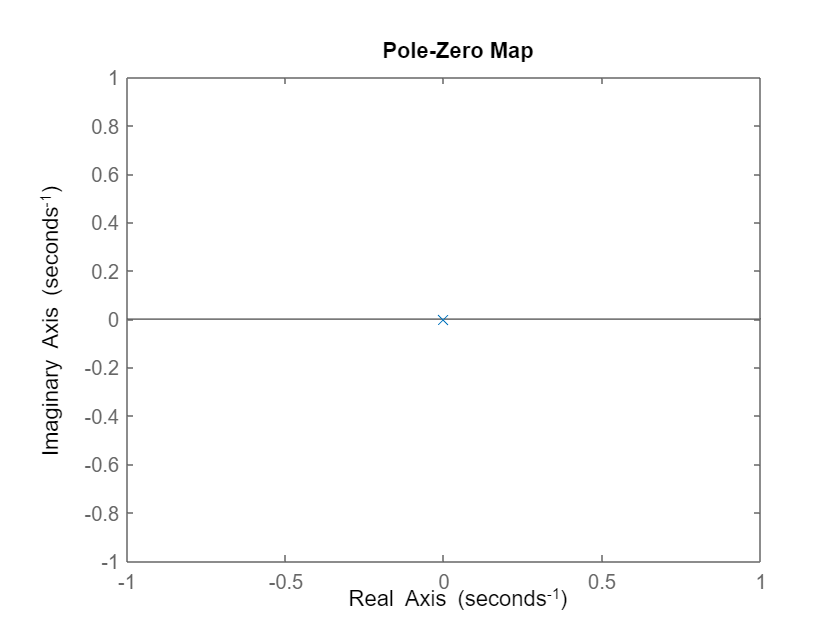

sys=ss(A_eq,B_eq,C,D);

% transfer function matrix :
Tf=tf(sys);
figure
pzmap(sys) % all poles on zero


% poles :
poles = pole(sys);
disp('Poles of the system:');

Poles of the system:


disp(poles);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0




% transmission zeros :
transmission_zeros = tzero(sys);
disp('Transmission Zeros of the MIMO system:');

Transmission Zeros of the MIMO system:


disp(transmission_zeros);
disp('This sys doesnt have any Zeros')

This sys doesnt have any Zeros


##   Q5)  Internal stability

% eigenvalues of A :
eigenvalues = eig(A_eq);
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(eigenvalues);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0




% Ensure the A matrix is stable
if any(real(eigenvalues) >= 0)
    disp('The system is not stable. Lyapunov stability check is not applicable.');
else
    % Define the Lyapunov equation: A'P + PA = -Q
    Q = eye(size(A_eq)); % Define a positive definite matrix Q
    try
        P = lyap(A_eq', Q); % Solve the Lyapunov equation
        disp('Lyapunov matrix P:');
        disp(P);

        % Check if P is positive definite
        if all(eig(P) > 0)
            disp('The Lyapunov matrix P is positive definite, confirming stability.');
        else
            disp('The Lyapunov matrix P is not positive definite.');
        end
    catch ME
        disp('Error solving Lyapunov equation:');
        disp(ME.message);
    end
end

The system is not stable. Lyapunov stability check is not applicable.


## Q6) State transition matrix

phi_L = inv(s*eye(length(A_eq))-A_eq);
disp(phi_L)

$$\begin{array}{l} \left(\begin{array}{cccccccccccc} \frac{1}{s} & \frac{1}{s^{2}} & 0 & 0 & 0 & 0 & 0 & \sigma_{1} & 0 & 0 & \sigma_{2} & 0\\ 0 & \frac{1}{s} & 0 & 0 & 0 & 0 & 0 & \sigma_{3} & 0 & 0 & \sigma_{1} & 0\\ 0 & 0 & \frac{1}{s} & \frac{1}{s^{2}} & 0 & 0 & -\sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0\\ 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & -\sigma_{3} & 0 & 0 & -\sigma_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{s} & \frac{1}{s^{2}} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & \frac{1}{s^{2}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & \frac{1}{s^{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & \frac{1}{s^{2}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981}{100\,s^{3}}\\ \sigma_{2}=\frac{981}{100\,s^{4}}\\ \sigma_{3}=\frac{981}{100\,s^{2}} \end{array}$$

phi_t = ilaplace(phi_L);
disp(phi_t)

$$\begin{array}{l} \left(\begin{array}{cccccccccccc} 1 & t & 0 & 0 & 0 & 0 & 0 & \sigma_{1} & 0 & 0 & \sigma_{2} & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & \frac{981\,t}{100} & 0 & 0 & \sigma_{1} & 0\\ 0 & 0 & 1 & t & 0 & 0 & -\sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & -\frac{981\,t}{100} & 0 & 0 & -\sigma_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & t & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & t & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & t & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & t\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,t^{2}}{200}\\ \sigma_{2}=\frac{327\,t^{3}}{200} \end{array}$$

x0 = transpose([0.1 0.1 3 1 4 0.34 1 0.01 1 0.1 3 1]) ;
Uin_s = transpose([1/s ,1/s,1/s,1/s]);
X = phi_L*x0 + phi_L*B_eq*Uin_s;
Y = C*X ;
y_t = ilaplace(Y)

$$y\_t = \left(\begin{array}{c} \frac{1635\,t^{4}}{14}+\frac{981\,t^{3}}{200}+\frac{981\,t^{2}}{20000}+\frac{t}{10}+\frac{1}{10}\\ -\frac{1635\,t^{4}}{14}-\frac{327\,t^{3}}{2000}-\frac{981\,t^{2}}{200}+t+3\\ \frac{t^{2}}{2}+\frac{17\,t}{50}+4\\ 100\,t^{2}+t+1 \end{array}\right)$$

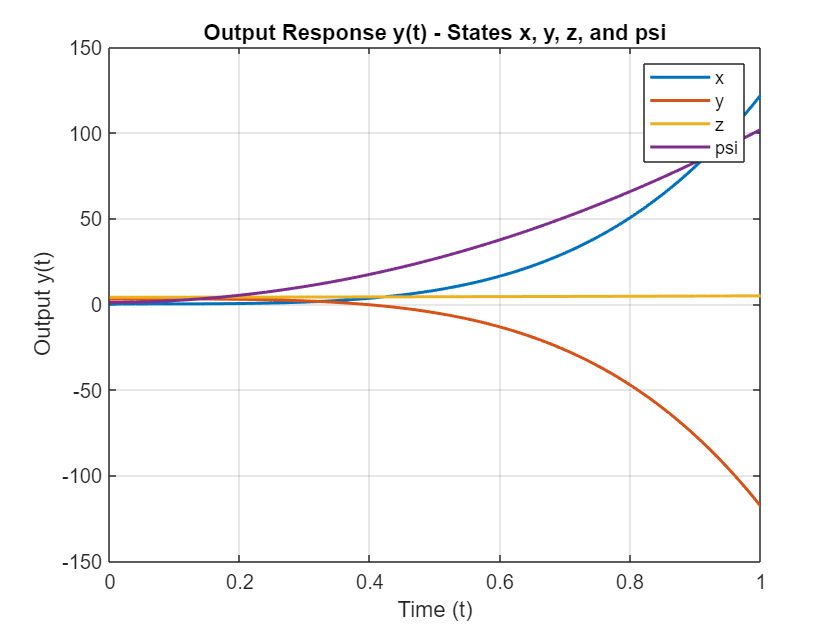

T = 0:0.01:1;
y_numeric = double(subs(y_t, t, T));

plot(T, y_numeric(1, :), 'DisplayName', 'x', 'LineWidth', 1.5);
hold on;
plot(T, y_numeric(2, :), 'DisplayName', 'y', 'LineWidth', 1.5);
plot(T, y_numeric(3, :), 'DisplayName', 'z', 'LineWidth', 1.5);
plot(T, y_numeric(4, :), 'DisplayName', 'psi', 'LineWidth', 1.5);
hold off;

xlabel('Time (t)');
ylabel('Output y(t)');
title('Output Response y(t) - States x, y, z, and psi');
legend('show');  
grid on;


% Uin_t = ilaplace(Uin_s);
% X_out = phi_t*x0.' + conv2(phi_t,B_eq *Uin_t.')

## **Q8)Nonlinear simulink**

% Define initial conditions :
Condition_1 = transpose([0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2]);
Condition_0 = transpose([0 0 0 0 0 0 0 0 0 0 0 0]);

x_0 = phi_t*Condition_1;
yout = C*x_0

$$yout = \left(\begin{array}{c} \frac{327\,t^{3}}{1000}+\frac{981\,t^{2}}{1000}+\frac{t}{5}+\frac{1}{5}\\ -\frac{327\,t^{3}}{1000}-\frac{981\,t^{2}}{1000}+\frac{t}{5}+\frac{1}{5}\\ \frac{t}{5}+\frac{1}{5}\\ \frac{t}{5}+\frac{1}{5} \end{array}\right)$$

## **Q9) Simulink**

## Q10) Controllability and Observability Matrix

n = size(A_eq, 1); % Number of state


Ctrb = ctrb(A_eq, B_eq);
Obsv = obsv(A_eq, C);


rank_Ctrb = rank(Ctrb);

rank_Obsv = rank(Obsv);


disp('Rank of Controllability Matrix:');

Rank of Controllability Matrix:


disp(rank_Ctrb);

    12




disp('Rank of Observability Matrix:');

Rank of Observability Matrix:


disp(rank_Obsv);

    12




if rank_Ctrb == n
    disp('The system is controllable.');
else
    disp('The system is not controllable.');
end

The system is controllable.



if rank_Obsv == n
    disp('The system is observable.');
else
    disp('The system is not observable.');
end

The system is observable.


% Compute eigenvalues and eigenvectors
[eigVec_C, eigVal_C] = eig(A_eq);
control_poles = diag(eigVal_C(rank(Ctrb) == n));

[eigVec_O, eigVal_O] = eig(A_eq');
observable_poles = diag(eigVal_O(rank(Obsv) == n));

disp('Controllable Poles:');

Controllable Poles:


disp(control_poles);

     0




disp('Observable Poles:');

Observable Poles:


disp(observable_poles);

     0



eigenvalues = eig(A_eq);

% Display eigenvalues
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(eigenvalues);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0




% Check stabilizability
if all(real(eigenvalues(rank(Ctrb) == n)) < 0)
    disp('The system is stabilizable.');
else
    disp('The system is not stabilizable.');
end

The system is not stabilizable.



% Check detectability
if all(real(eigenvalues(rank(Obsv) == n)) < 0)
    disp('The system is detectable.');
else
    disp('The system is not detectable.');
end

The system is not detectable.


## **Q11) Kalman Decomposition**

[A_bar, B_bar, C_bar, T, k] = ctrbf(A_eq, B_eq, C);


disp('Transformation Matrix T:');

Transformation Matrix T:


disp(T);

         0         0   -1.0000         0         0         0    0.0000         0         0         0    0.0000         0
   -1.0000         0         0         0         0         0         0         0         0         0         0         0
         0   -1.0000         0         0         0         0         0    0.0000         0    0.0000         0         0
         0         0         0   -1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0  

disp('Rank of Transformation Matrix T:');

Rank of Transformation Matrix T:


disp(rank(T));

    12





A_bar = T \ A_eq * T;
B_bar = T \ B_eq;
C_bar = C * T;


numC = k(1);  % Dimension of controllable subspace
numO = k(2);  % Dimension of observable subspace
numUC = size(A_eq, 1) - numC; % Dimension of uncontrollable subspace
numUO = size(A_eq, 1) - numO; % Dimension of unobservable subspace

% Partition A_bar into subsystems
A_CObar = A_bar(1:numC, 1:numO);           % Controllable and observable
A_CO = A_bar(1:numC, numO+1:end);          % Controllable and unobservable
A_CbarO = A_bar(numC+1:end, 1:numO);       % Uncontrollable and observable
A_CbarObar = A_bar(numC+1:end, numO+1:end);% Uncontrollable and unobservable

% Partition B_bar
B_CObar = B_bar(1:numC, :);                % Input matrix for controllable/observable subsystem
B_CbarO = B_bar(numC+1:end, :);            % Input matrix for uncontrollable/observable subsystem

% Partition C_bar
C_CObar = C_bar(:, 1:numO);                % Output matrix for controllable/observable subsystem
C_CbarO = C_bar(:, numO+1:end);            % Output matrix for controllable/unobservable subsystem

% Display subsystem matrices
disp('Subsystem Matrices:');

Subsystem Matrices:


disp('A_CObar (Controllable and Observable part of A):');

A_CObar (Controllable and Observable part of A):


disp(A_CObar);

         0         0         0         0
         0         0         0    1.0000
    1.0000         0         0         0
         0         0         0         0




disp('A_CO (Controllable and Unobservable part of A):');

A_CO (Controllable and Unobservable part of A):


disp(A_CO);

   -9.8100         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0
         0         0         0         0    9.8100         0         0         0




disp('A_CbarO (Uncontrollable and Observable part of A):');

A_CbarO (Uncontrollable and Observable part of A):


disp(A_CbarO);

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0




disp('A_CbarObar (Uncontrollable and Unobservable part of A):');

A_CbarObar (Uncontrollable and Unobservable part of A):


disp(A_CbarObar);

         0         0         0         0         0         0   -1.0000         0
         0         0         0         0         0    1.0000         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   -1.0000
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0




disp('B_CObar (Controllable and Observable part of B):');

B_CObar (Controllable and Observable part of B):


disp(B_CObar);

   1.0e-13 *

         0         0         0         0
    0.0022         0         0   -0.4441
         0         0   -0.6344         0
         0         0         0         0




disp('B_CbarO (Uncontrollable and Observable part of B):');

B_CbarO (Uncontrollable and Observable part of B):


disp(B_CbarO);

         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000         0         0         0
         0         0         0         0
         0         0         0 -200.0000
         0         0 -285.7143         0
         0 -285.7143         0         0




disp('C_CObar (Controllable and Observable part of C):');

C_CObar (Controllable and Observable part of C):


disp(C_CObar);

         0         0   -1.0000         0
         0   -1.0000         0         0
         0         0         0         0
         0         0         0         0




disp('C_CbarO (Controllable and Unobservable part of C):');

C_CbarO (Controllable and Unobservable part of C):


disp(C_CbarO);

         0         0    0.0000         0         0         0    0.0000         0
         0         0         0    0.0000         0    0.0000         0         0
         0         0    1.0000         0         0         0         0         0
         0   -1.0000         0         0         0         0         0         0




% Use minreal to obtain a reduced order model for the controllable and observable subsystem
sys = ss(A_CObar, B_CObar, C_CObar, D);
[sysr, U] = minreal(sys);

2 states removed.



% Display reduced system matrices
disp('Reduced System (A, B, C, D) for Controllable and Observable Subsystem:');

Reduced System (A, B, C, D) for Controllable and Observable Subsystem:



disp(sysr.A);

     0     0
     0     0




disp(sysr.B);

   1.0e-13 *

    0.0022         0         0   -0.4441
         0         0   -0.6344         0




disp(sysr.C);

         0   -1.0000
   -1.0000         0
         0         0
         0         0




disp(sysr.D);

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0

